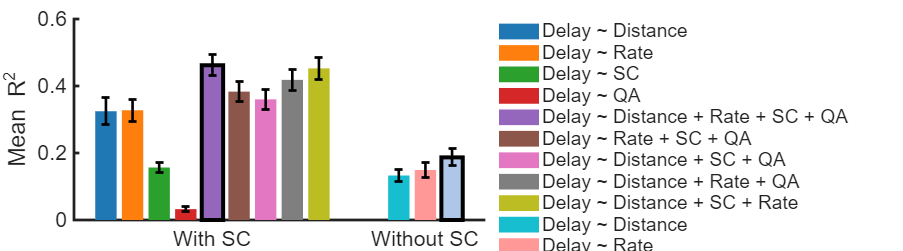

clc; clear;
%% ---------------- Load with-fiber results ----------------
Path = 'step4_IEDtw_TD-6d0_IT-100ms_fitting';
load(fullfile(Path, 'op9_IEDtw_delay_ED_rate_fibN_fibQA_fitting.mat'));
N = 0;
for nS = 1:length(IEDtwDelay_fitting)
    A = IEDtwDelay_fitting{nS};
    if ~isempty(A)
        N = N + 1;
        for n = 1:length(A)
            R2(n, N, 1) = A{n}.delay_ED_R2;
            R2(n, N, 2) = A{n}.delay_rate_R2;
            R2(n, N, 3) = A{n}.delay_fibN_R2;
            R2(n, N, 4) = A{n}.delay_fibQA_R2;
            R2(n, N, 5) = A{n}.delay_R2;
            R2(n, N, 6) = A{n}.delay_noED_R2;
            R2(n, N, 7) = A{n}.delay_noRate_R2;
            R2(n, N, 8) = A{n}.delay_noFibN_R2;
            R2(n, N, 9) = A{n}.delay_noFibQA_R2;
        end
    end
end
R2(R2 <= 0) = 0;
R2 = squeeze(mean(R2, 1));   % subject × model
R2_mean = mean(R2, 1, 'omitnan');
R2_sem  = std(R2, 0, 1, 'omitnan') ./ sqrt(size(R2, 1));

%% ---------------- Load no-fiber results ----------------
load(fullfile(Path, 'op10_IEDtw_delay_ED_rate_nofib_fitting.mat'));
N = 0;
for nS = 1:length(IEDtwDelay_fitting_nofib)
    A = IEDtwDelay_fitting_nofib{nS};
    if ~isempty(A)
        N = N + 1;
        for n = 1:length(A)
            R2_nofib(n, N, 1) = A{n}.delay_ED_R2;
            R2_nofib(n, N, 2) = A{n}.delay_rate_R2;
            R2_nofib(n, N, 3) = A{n}.delay_R2;
        end
    end
end
R2_nofib(R2_nofib <= 0) = 0;
R2_nofib = squeeze(mean(R2_nofib, 1));   % subject × model
R2_nofib_mean = mean(R2_nofib, 1, 'omitnan');
R2_nofib_sem  = std(R2_nofib, 0, 1, 'omitnan') ./ sqrt(size(R2_nofib, 1));

%% ---------------- High-Resolution Colors ----------------
high_res_colors = [31,  119, 180; 255, 127, 14;  44,  160, 44;  214, 39,  40;
                   148, 103, 189; 140, 86,  75;  227, 119, 194; 127, 127, 127;
                   188, 189, 34;  23,  190, 207; 255, 152, 150; 174, 199, 232] / 255;
colors_fiber = high_res_colors(1:9, :);
colors_nofiber = high_res_colors(10:12, :);

%% ---------------- Model names for legend ----------------
model_names_fiber = {'Delay ~ Distance',
                    'Delay ~ Rate',
                    'Delay ~ SC',
                    'Delay ~ QA',
                    'Delay ~ Distance + Rate + SC + QA',
                    'Delay ~ Rate + SC + QA',
                    'Delay ~ Distance + SC + QA',
                    'Delay ~ Distance + Rate + QA',
                    'Delay ~ Distance + SC + Rate'};
model_names_nofiber = {'Delay ~ Distance',
                        'Delay ~ Rate',
                        'Delay ~ Distance + Rate'};
%% ---------------- Plot ----------------
figure('Color', 'w', 'Units', 'centimeters', 'Position', [5, 5, 36, 10]); hold on;
% x positions
x_fiber = 1:9; x_nofiber = 12:14;

% Plot with-fiber models
h_bars = [];
for i = 1:9
    h = bar(x_fiber(i), R2_mean(i), 0.8, ...
        'FaceColor', colors_fiber(i,:), 'EdgeColor', 'none', 'DisplayName', model_names_fiber{i});
    h_bars = [h_bars, h];
end
[~, best_fiber_idx] = max(R2_mean);
bar(x_fiber(best_fiber_idx), R2_mean(best_fiber_idx), 0.8, ...
    'LineWidth', 3, 'FaceColor', colors_fiber(best_fiber_idx,:), 'EdgeColor', [0, 0, 0]);
errorbar(x_fiber, R2_mean, R2_sem, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Plot no-fiber models
for i = 1:3
    h = bar(x_nofiber(i), R2_nofib_mean(i), 0.8, ...
        'FaceColor', colors_nofiber(i,:), 'EdgeColor', 'none', 'DisplayName', model_names_nofiber{i});
    h_bars = [h_bars, h];
end
[~, best_nofiber_idx] = max(R2_nofib_mean);
bar(x_nofiber(best_nofiber_idx), R2_nofib_mean(best_nofiber_idx), 0.8, ...
    'LineWidth', 3, 'FaceColor', colors_nofiber(best_nofiber_idx,:), 'EdgeColor', [0, 0, 0]);
errorbar(x_nofiber, R2_nofib_mean, R2_nofib_sem, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Add legend for all models
legend(h_bars, 'NumColumns', 1, 'Location', 'eastoutside', 'Box', 'off');
ylabel('Mean R^2');
box off; hold off;

% Set x-axis to show only group labels
set(gca, 'XTick', [mean(x_fiber), mean(x_nofiber)]); % Midpoints of each group
set(gca, 'XTickLabel', {'With SC', 'Without SC'});
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

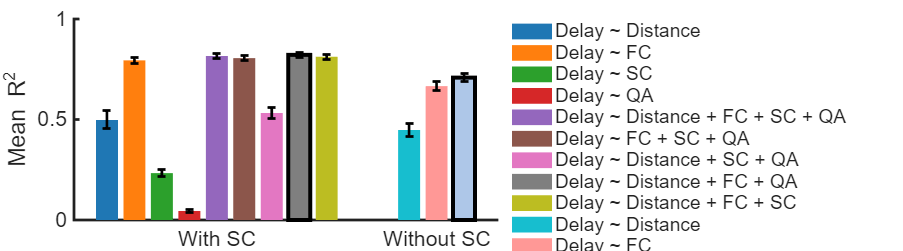

clc; clear;
Path = 'step5_IEDxcorr_TD-6d0_IT-100ms_fitting';
load(fullfile(Path, 'op4_delay_ED_FC_fibN_fibQA_fitting.mat'));
N = 0;
for nS = 1:length(IEDxcDelay_fitting)
    A = IEDxcDelay_fitting{nS};
    if ~isempty(A)
        N = N + 1;
        for n = 1:length(A)
            R2(n, N, 1) = A{n}.delay_ED_R2;
            R2(n, N, 2) = A{n}.delay_xcFC_R2;
            R2(n, N, 3) = A{n}.delay_fibN_R2;
            R2(n, N, 4) = A{n}.delay_fibQA_R2;
            R2(n, N, 5) = A{n}.delay_R2;
            R2(n, N, 6) = A{n}.delay_noED_R2;
            R2(n, N, 7) = A{n}.delay_noFC_R2;
            R2(n, N, 8) = A{n}.delay_noFibN_R2;
            R2(n, N, 9) = A{n}.delay_noFibQA_R2;
        end
    end
end
R2(R2 <= 0) = 0;
R2 = squeeze(mean(R2, 1));   % subject × model
R2_mean = mean(R2, 1, 'omitnan');
R2_sem  = std(R2, 0, 1, 'omitnan') ./ sqrt(size(R2, 1));

%% ---------------- Load no-fiber results ----------------
load(fullfile(Path, 'op5_delay_ED_FC_noFib_fitting.mat'));
N = 0;
for nS = 1:length(IEDxcDelay_fitting_nofib)
    A = IEDxcDelay_fitting_nofib{nS};
    if ~isempty(A)
        N = N + 1;
        for n = 1:length(A)
            R2_nofib(n, N, 1) = A{n}.delay_ED_R2;
            R2_nofib(n, N, 2) = A{n}.delay_xcFC_R2;
            R2_nofib(n, N, 3) = A{n}.delay_R2;
        end
    end
end
R2_nofib(R2_nofib <= 0) = 0;
R2_nofib = squeeze(mean(R2_nofib, 1));   % subject × model
R2_nofib_mean = mean(R2_nofib, 1, 'omitnan');
R2_nofib_sem  = std(R2_nofib, 0, 1, 'omitnan') ./ sqrt(size(R2_nofib, 1));

%% ---------------- High-Resolution Colors ----------------
high_res_colors = [31,  119, 180; 255, 127, 14;  44,  160, 44;  214, 39,  40;
                   148, 103, 189; 140, 86,  75;  227, 119, 194; 127, 127, 127;
                   188, 189, 34;  23,  190, 207; 255, 152, 150; 174, 199, 232] / 255;
colors_fiber = high_res_colors(1:9, :);
colors_nofiber = high_res_colors(10:12, :);

%% ---------------- Model names for legend ----------------
model_names_fiber = {'Delay ~ Distance',
                    'Delay ~ FC',
                    'Delay ~ SC',
                    'Delay ~ QA',
                    'Delay ~ Distance + FC + SC + QA',
                    'Delay ~ FC + SC + QA',
                    'Delay ~ Distance + SC + QA',
                    'Delay ~ Distance + FC + QA',
                    'Delay ~ Distance + FC + SC'};
model_names_nofiber = {'Delay ~ Distance',
                        'Delay ~ FC',
                        'Delay ~ Distance + FC'};
%% ---------------- Plot ----------------
figure('Color', 'w', 'Units', 'centimeters', 'Position', [5, 5, 36, 10]); hold on;
% x positions
x_fiber = 1:9; x_nofiber = 12:14;

% Plot with-fiber models
h_bars = [];
for i = 1:9
    h = bar(x_fiber(i), R2_mean(i), 0.8, ...
        'FaceColor', colors_fiber(i,:), 'EdgeColor', 'none', 'DisplayName', model_names_fiber{i});
    h_bars = [h_bars, h];
end
[~, best_fiber_idx] = max(R2_mean);
bar(x_fiber(best_fiber_idx), R2_mean(best_fiber_idx), 0.8, ...
    'LineWidth', 3, 'FaceColor', colors_fiber(best_fiber_idx,:), 'EdgeColor', [0, 0, 0]);
errorbar(x_fiber, R2_mean, R2_sem, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Plot no-fiber models
for i = 1:3
    h = bar(x_nofiber(i), R2_nofib_mean(i), 0.8, ...
        'FaceColor', colors_nofiber(i,:), 'EdgeColor', 'none', 'DisplayName', model_names_nofiber{i});
    h_bars = [h_bars, h];
end
[~, best_nofiber_idx] = max(R2_nofib_mean);
bar(x_nofiber(best_nofiber_idx), R2_nofib_mean(best_nofiber_idx), 0.8, ...
    'LineWidth', 3, 'FaceColor', colors_nofiber(best_nofiber_idx,:), 'EdgeColor', [0, 0, 0]);
errorbar(x_nofiber, R2_nofib_mean, R2_nofib_sem, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Add legend for all models
legend(h_bars, 'NumColumns', 1, 'Location', 'eastoutside', 'Box', 'off');
ylabel('Mean R^2');
box off; hold off;

% Set x-axis to show only group labels
set(gca, 'XTick', [mean(x_fiber), mean(x_nofiber)]); % Midpoints of each group
set(gca, 'XTickLabel', {'With SC', 'Without SC'});
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

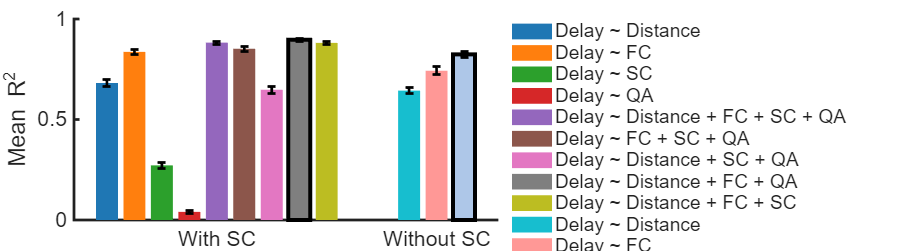

clc; clear;
Path = 'step6_NAxcorr_TD-6d0_IT-100ms_fitting';
load(fullfile(Path, 'op5_delay_ED_FC_fibN_fibQA_fitting.mat'));
N = 0;
for nS = 1:length(NAxcDelay_fitting)
    A = NAxcDelay_fitting{nS};
    if ~isempty(A)
        N = N + 1;
        for n = 1:length(A)
            R2(n, N, 1) = A{n}.delay_ED_R2;
            R2(n, N, 2) = A{n}.delay_xcFC_R2;
            R2(n, N, 3) = A{n}.delay_fibN_R2;
            R2(n, N, 4) = A{n}.delay_fibQA_R2;
            R2(n, N, 5) = A{n}.delay_R2;
            R2(n, N, 6) = A{n}.delay_noED_R2;
            R2(n, N, 7) = A{n}.delay_noFC_R2;
            R2(n, N, 8) = A{n}.delay_noFibN_R2;
            R2(n, N, 9) = A{n}.delay_noFibQA_R2;
        end
    end
end
R2(R2 <= 0) = 0;
R2 = squeeze(mean(R2, 1));   % subject × model
R2_mean = mean(R2, 1, 'omitnan');
R2_sem  = std(R2, 0, 1, 'omitnan') ./ sqrt(size(R2, 1));

%% ---------------- Load no-fiber results ----------------
load(fullfile(Path, 'op6_delay_ED_FC_noFib_fitting.mat'));
N = 0;
for nS = 1:length(NAxcDelay_fitting_nofib)
    A = NAxcDelay_fitting_nofib{nS};
    if ~isempty(A)
        N = N + 1;
        for n = 1:length(A)
            R2_nofib(n, N, 1) = A{n}.delay_ED_R2;
            R2_nofib(n, N, 2) = A{n}.delay_xcFC_R2;
            R2_nofib(n, N, 3) = A{n}.delay_R2;
        end
    end
end
R2_nofib(R2_nofib <= 0) = 0;
R2_nofib = squeeze(mean(R2_nofib, 1));   % subject × model
R2_nofib_mean = mean(R2_nofib, 1, 'omitnan');
R2_nofib_sem  = std(R2_nofib, 0, 1, 'omitnan') ./ sqrt(size(R2_nofib, 1));

%% ---------------- High-Resolution Colors ----------------
high_res_colors = [31,  119, 180; 255, 127, 14;  44,  160, 44;  214, 39,  40;
                   148, 103, 189; 140, 86,  75;  227, 119, 194; 127, 127, 127;
                   188, 189, 34;  23,  190, 207; 255, 152, 150; 174, 199, 232] / 255;
colors_fiber = high_res_colors(1:9, :);
colors_nofiber = high_res_colors(10:12, :);

%% ---------------- Model names for legend ----------------
model_names_fiber = {'Delay ~ Distance',
                    'Delay ~ FC',
                    'Delay ~ SC',
                    'Delay ~ QA',
                    'Delay ~ Distance + FC + SC + QA',
                    'Delay ~ FC + SC + QA',
                    'Delay ~ Distance + SC + QA',
                    'Delay ~ Distance + FC + QA',
                    'Delay ~ Distance + FC + SC'};
model_names_nofiber = {'Delay ~ Distance',
                        'Delay ~ FC',
                        'Delay ~ Distance + FC'};
%% ---------------- Plot ----------------
figure('Color', 'w', 'Units', 'centimeters', 'Position', [5, 5, 36, 10]); hold on;
% x positions
x_fiber = 1:9; x_nofiber = 12:14;

% Plot with-fiber models
h_bars = [];
for i = 1:9
    h = bar(x_fiber(i), R2_mean(i), 0.8, ...
        'FaceColor', colors_fiber(i,:), 'EdgeColor', 'none', 'DisplayName', model_names_fiber{i});
    h_bars = [h_bars, h];
end
[~, best_fiber_idx] = max(R2_mean);
bar(x_fiber(best_fiber_idx), R2_mean(best_fiber_idx), 0.8, ...
    'LineWidth', 3, 'FaceColor', colors_fiber(best_fiber_idx,:), 'EdgeColor', [0, 0, 0]);
errorbar(x_fiber, R2_mean, R2_sem, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Plot no-fiber models
for i = 1:3
    h = bar(x_nofiber(i), R2_nofib_mean(i), 0.8, ...
        'FaceColor', colors_nofiber(i,:), 'EdgeColor', 'none', 'DisplayName', model_names_nofiber{i});
    h_bars = [h_bars, h];
end
[~, best_nofiber_idx] = max(R2_nofib_mean);
bar(x_nofiber(best_nofiber_idx), R2_nofib_mean(best_nofiber_idx), 0.8, ...
    'LineWidth', 3, 'FaceColor', colors_nofiber(best_nofiber_idx,:), 'EdgeColor', [0, 0, 0]);
errorbar(x_nofiber, R2_nofib_mean, R2_nofib_sem, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Add legend for all models
legend(h_bars, 'NumColumns', 1, 'Location', 'eastoutside', 'Box', 'off');
ylabel('Mean R^2');
box off; hold off;

% Set x-axis to show only group labels
set(gca, 'XTick', [mean(x_fiber), mean(x_nofiber)]); % Midpoints of each group
set(gca, 'XTickLabel', {'With SC', 'Without SC'});
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);